close all
clear
clc

准备工作

T = 60;
N = 1000;
OMG1 = 50;
REP = 29;
[t,omg,FT,IFT] = prefourier([-T/2,T/2],N,[-REP/2,REP/2],REP*OMG1);

定义三角频谱，逆变换计算时域波形

G = tripuls(omg);
g = IFT*G;

## 思路一：对频域周期延拓，观察时域抽样现象

将三角谱重复若干次得到周期谱（取出三角谱中非零部分和一个周期冲激序列做卷积）

temp = 0*G;
temp(1:OMG1:REP*OMG1) = 1;
G1 = filter(G(G>0),1,temp);

对周期三角谱逆变换得到抽样的时域波形

g1 = IFT*G1;

## 思路二：对时域抽样，观察频域周期延拓现象

对原时域波形进行抽样，再计算其频谱

g2 = 0*g;
g2(1:3*N/T:N) = g(1:3*N/T:N);
G2 = FT*g2;

绘图：左列是波形，右列是频谱，由上到下依次是原信号、思路一结果和思路二结果

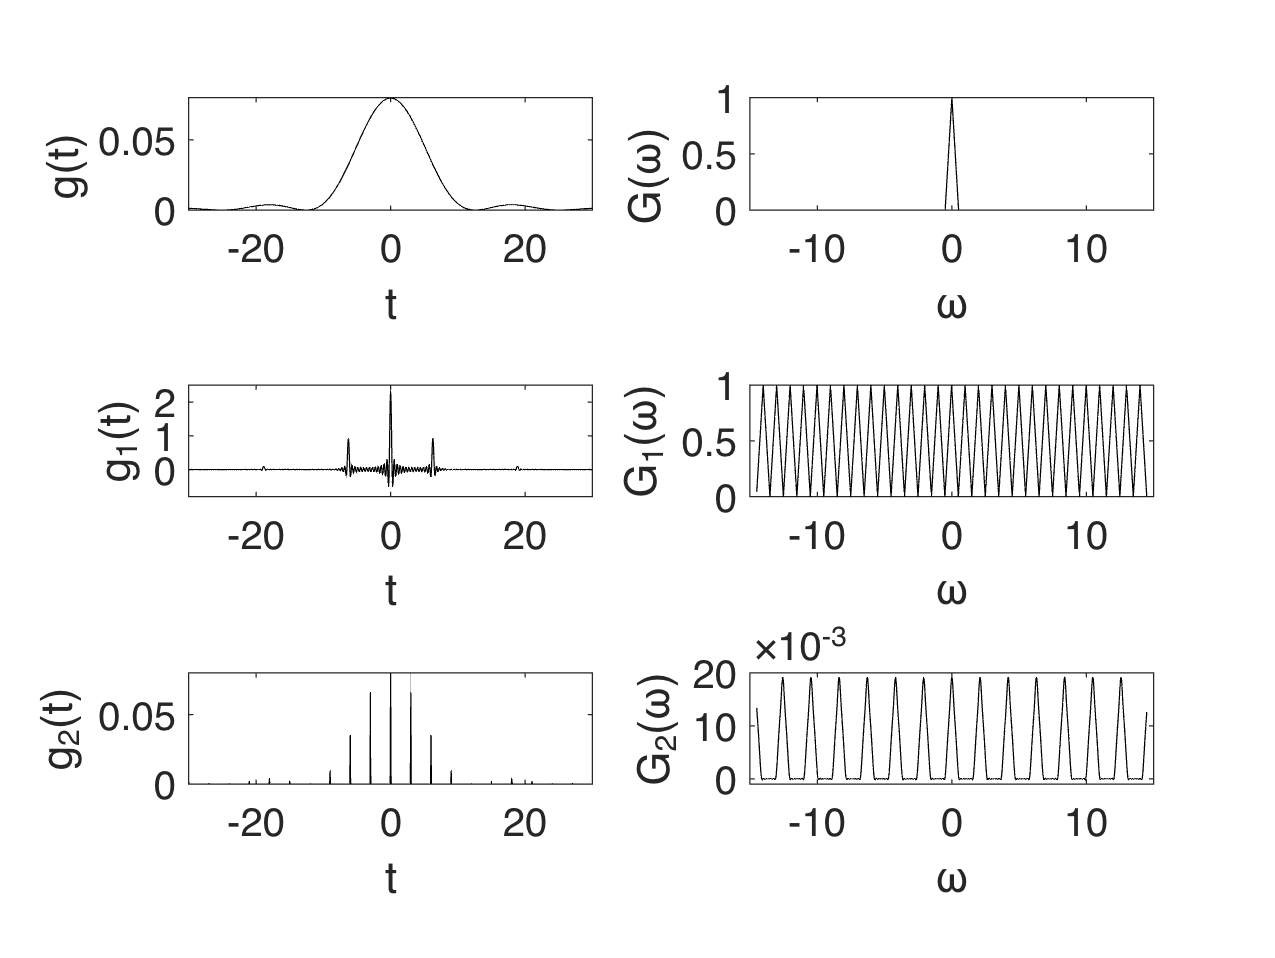

figure;
dat = [g,g1,g2];
ylim = [0,0.08;-0.8,2.5;0,0.08];
ylab = ['g(t)  ';'g_1(t)';'g_2(t)'];
for n = 1:3
    subplot(3,2,2*n-1), hold on, box on;
    plot(t,real(dat(:,n)),'k');
    set(gca,'FontSize',16,'XLim',[-30 30],'YLim',ylim(n,:));
    xlabel('t');
    ylabel(ylab(n,:));
end

dat = [G,G1,G2];
ylim = [0,1;0,1;-1e-3,20e-3];
ylab = ['G(\omega)  ';'G_1(\omega)';'G_2(\omega)'];
for n = 1:3
    subplot(3,2,2*n), hold on, box on;
    plot(omg,real(dat(:,n)),'k');
    set(gca,'FontSize',16,'XLim',[-15 15],'YLim',ylim(n,:));
    xlabel('\omega');
    ylabel(ylab(n,:));
end